load classdata.mat

%Creates a cell array with the names of the people
Names = cell(1,66);
for i = 1:66
    Names(1,i) = y.name(1,2*i);    
end

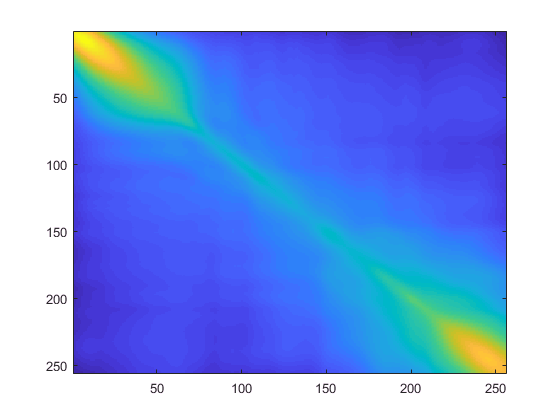

AverageClassFaces = zeros(256,256,66);
for i = 1:66
    AverageClassFaces(:,:,i) = (grayfaces(:,:,2*i)+grayfaces(:,:,2*i-1))/2 ;
end

TotalAverageFace = zeros(256,256);
for i = 1:132
    TotalAverageFace = TotalAverageFace + grayfaces(:,:,i);
end
TotalAverageFace = TotalAverageFace./132;

Sb = zeros(256,256);
for i = 1:66
    Sb = Sb + (2*(AverageClassFaces(:,:,i)-TotalAverageFace)*(AverageClassFaces(:,:,i)-TotalAverageFace).') ;
end
imagesc(Sb)

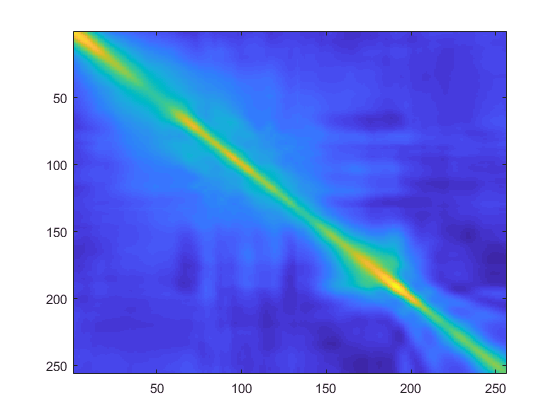


Sw = zeros(256,256);
for i = 1:66
    InsideWithin2 = zeros(256,256);
   for k = 1:2
       InsideWithin1 = (grayfaces(:,:,2*i-2+k) - AverageClassFaces(:,:,i)) * (grayfaces(:,:,2*i-2+k) - AverageClassFaces(:,:,i)).' ;
       InsideWithin2 = InsideWithin2 + InsideWithin1;
   end
    Sw = Sw + InsideWithin2;
end
imagesc(Sw)

% Create Weights and Eigenfaces for Fisherface analysis
faces = grayfaces;
names = Names;
limit = 132;
sFaces = stackim(faces);  % faces stacked in column vectors
nFaces = (sFaces - mean(sFaces,1))./sqrt(length(sFaces(:,1)));  % normalize faces
fCovarriance = nFaces'*nFaces;  % covarriance matrix of faces
[V,D] = eig(fCovarriance);
AllEigenFaces = sFaces*fliplr(V);  % flip Eigenfaces so strongest is first
EigenFaces = AllEigenFaces(:,1:limit);  % limit eigenfaces (and weights indirectly)
allWeights = linsolve(EigenFaces,nFaces);  % generate weights for training set
% allWeights = EigenFaces\nFaces;
limitedWeights = allWeights(end-limit+1:end,:);

% Sb of faces in Eigenspace
AverageClassFaces = zeros(132,66);
for i = 1:66  % create average face for each class (person)
    AverageClassFaces(:,i) = (allWeights(:,2*i)+allWeights(:,2*i-1))/2 ;
end

TotalAverageFace = zeros(132,1);
for i = 1:132  % create average face of all faces
    TotalAverageFace = TotalAverageFace + allWeights(:,i);
end
TotalAverageFace = TotalAverageFace./132;

Sb = zeros(132,132);
for i = 1:66
    Sb = Sb + (2*(AverageClassFaces(:,i)-TotalAverageFace)*(AverageClassFaces(:,i)-TotalAverageFace).') ;
end

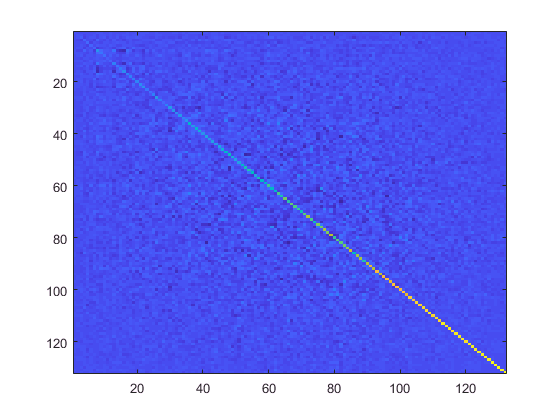

% Sw of faces in Eigenspace
Sw = zeros(132,132);
for i = 1:66
    InsideWithin2 = zeros(132,132);
   for k = 1:2
       InsideWithin1 = (allWeights(:,2*i-2+k) - AverageClassFaces(:,i)) * (allWeights(:,2*i-2+k) - AverageClassFaces(:,i)).' ;
       InsideWithin2 = InsideWithin2 + InsideWithin1;
   end
    Sw = Sw + InsideWithin2;
end
imagesc(Sw)

% Wopt
[Wopt,D] = eig(Sb,Sw);

% Names
[Names,ia,ic] = unique(names);  % get unique names and their indices

% Get new weights of faces with Wopt
newWeights = linsolve(Wopt,allWeights);

% Does this make sense?
% To do a "quick" check, compare the relative distances between
% images of the same class in fisher weights and eigen weights

edist = zeros(132,132);
for i = 1:132
    image1 = allWeights(:,i);
    for j = 1:132
        image2 = allWeights(:,j);
        edist(i,j) = eucDist(image1,image2);
    end
end

fdist = zeros(132,132);
for i = 1:132
    image1 = newWeights(:,i);
    for j = 1:132
        image2 = newWeights(:,j);
        fdist(i,j) = eucDist(image1,image2);
    end
end

eidist = edist(sub2ind(size(edist),1:2:132,2:2:132));
fidist = fdist(sub2ind(size(fdist),1:2:132,2:2:132));
idr = eidist./fidist;  % ratio of differences
mean(idr)

ans = 2.9640

min(idr)

ans = 1.5315

max(idr)

ans = 3.4174

median(idr)

ans = 3.0609

% indices for eodist and fodist
rows = [];
cols = [];
dim = length(fidist(1,:));
for i = 1:2:dim
    rows = [rows [i+2:dim] [i+2:dim]];
    cols = [cols i*ones(1,dim - (i + 1)) (i+1)*ones(1,dim - (i + 1))];
end

eodist = edist(sub2ind(size(edist),rows,cols));
fodist = fdist(sub2ind(size(fdist),rows,cols));

odr = eodist./fodist;
mean(odr)

ans = 2.8757

min(odr)

ans = 1.6198

max(odr)

ans = 3.3271

median(odr)

ans = 2.9419

[Classes,in,ic] = unique(y.name);

% actually using fisher faces
model.fisherfaces = EigenFaces*Wopt;
fisherWeights = model.fisherfaces'*reshape(grayfaces,256^2,132,1);
classedWeights = zeros(length(fisherWeights(:,1)),length(Classes));
for i = 1:length(Classes)
    weightsToAverage = fisherWeights(:,ic == i);  % get all weights under the same class (person)
    classedWeights(:,i) = sum(weightsToAverage,2)./length(weightsToAverage(1,:));  % average weights to single vector
end
% classedWeights = classedWeights(1:limit,:);

model.weights = classedWeights;
model.names = Classes;
model.eigenfaces = EigenFaces;

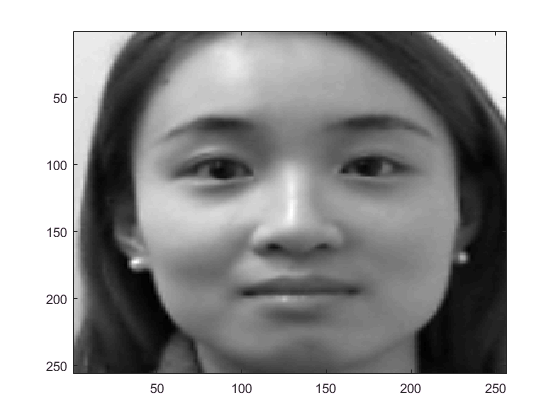

testImage = grayfaces(:,:,132);
figure; colormap gray
imagesc(testImage)

testWeights = model.fisherfaces'*reshape(testImage,256^2,1,1);
distances = sqrt(sum((classedWeights - testWeights).^2, 1));  % compute Euclidean distances

[Distances,NameIndices] = sort(distances)

Distances =    1.0e+10 *

    0.0513    0.1113    0.1323    0.1903    0.2076    0.2166    0.2328    0.2455    0.2567    0.2594    0.2720    0.2799    0.2866    0.2995    0.3268    0.3470    0.3696    0.3763    0.3766    0.3892    0.4027    0.4095    0.4492    0.4623    0.4645    0.4892    0.5360    0.5447    0.5705    0.5752    0.5868    0.6105    0.6668    0.7127    0.7196    0.7437    0.7749    0.8236    0.8343    0.8533    0.8562    0.9074    0.9111    0.9780    0.9881    1.1511    1.1826    1.2241    1.2263    1.2454


NameIndices =     66    17    30     6    43    56    13    23    34    51    45    20    40    54    57    12    62    59    35    10    52    50    24    38    47    15     9     5    32    29    55    33     1    16    64     3    53    42    19    49    21    44     7     2    14    18    27    65    46    26


model.names(NameIndices(1:10))

ans = 1×10 cell array
    'xieruishen'    'emilynasif'    'jillianmacgregor'    'amyphung'    'mayacalabria'    'sarahdeng'    'coreycochran-lepiz'    'flynnmichael-legg'    'julianstone'    'quinnkelley'


function D = eucDist(A,B)
    D = sqrt(sum((A - B).^2, 1));
end